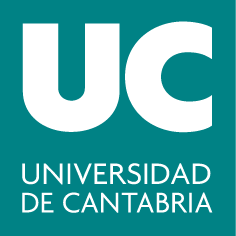

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 4: Sistemas de ecuaciones lineales (I)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Resolución de sistemas compatibles determinados (no homogéneos)

- Resolución de sistemas compatibles indeterminados (no homogéneos)

- Resolución de sistemas homogéneos

**Resolución de sistemas compatibles determinados (no homogéneos)**

Siempre que estemos frente a un sistema de ecuaciones lineales, lo primero que haremos es clasificarlo (si es incompatible, no habrá nada más que hacer). Para ello, partiendo de la matriz de coeficientes y la matriz ampliada del sistema, aplicaremos el teorema de Rouché-Fröbenius. Vamos a verlo con el siguiente ejemplo:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y - z & = & 0\\ 
			 3x + y -z & = & 2\\
			 4x - 2y + z & = & 3\\  
		 \end{array}\right.$$


% clasifico el sistema
A = [1 1 -1; 3 1 -1; 4 -2 1]; % matriz de coeficientes
b = [0 2 3]';  % vector de términos independienets
Aamp = [A, b];  % matriz ampliada
[rank(A), rank(Aamp)]  % R-F: sistema compatible determinado

ans =      3     3


Una vez hemos comprobado que el sistema es compatible determinado (habrá una única solución), veremos a continuación distintas formas de resolver este tipo de sistemas:

Método 1: Si existe, utilizar la matriz $A^{-1}$ para despejar el vector de incógnitas $\vec{x}$ en la ecuación matricial del sistema, $A\vec{x}=\vec{b}$

inv(A)*b  % solución: (x=1, y=2, z=3)

ans =      1
     2
     3


Método 2: Calcular la forma escalonada reducida por filas de la matriz ampliada del sistema (método de Gauss-Jordan).

rref(Aamp)  % solución: (x=1, y=2, z=3)

ans =      1     0     0     1
     0     1     0     2
     0     0     1     3


Método 3: Con la función *linsolve *(usa distintos tipos de factorización de matrices para resolver el sistema). Requiere como entradas la matriz de coeficientes y el vector de términos independientes.

linsolve(A, b)  % solución: (x=1, y=2, z=3)

ans =     1.0000
    2.0000
    3.0000


Método 4: Con el operador "\". Al igual que para *linsolve,* necesitaremos la matriz de coeficientes y el vector de términos independientes.

A\b  % solución: (x=1, y=2, z=3)

ans =     1.0000
    2.0000
    3.0000


Método 5: Definiendo las incógnitas del sistema como simbólicas y resolviendo su ecuación matricial con la función *solve*.

syms x y z real  % defino las incógnitas del sistema como variables simbólicas
X = [x y z]';  % vector de incógnitas simbólicas
sol = solve(A*X == b);  % resuelvo el sistema en su forma matricial

La variable *sol *será un tipo de objeto de MATLAB que se denomina estructura. Las estructuras están compuestas por distintos campos, a los que se puede acceder a través del operador ".".

[sol.x, sol.y, sol.z]  % solución: (x=1, y=2, z=3)

$$ans = \left(\begin{array}{ccc} 1 & 2 & 3 \end{array}\right)$$

Como vemos, cualquiera de los cinco métodos presentados conducen a la misma solución. Siempre es **altamente recomendable **comprobar que esa solución a la que hemos llegado es correcta, es decir, que cumple todas las ecuaciones del sistema simultáneamente (satisface su ecuación matricial).

sol = A\b;
A*sol - b  % comprobación: A*sol = b

ans =      0
     0
     0


**Resolución de sistemas compatibles indeterminados (no homogéneos)**

En el caso de sistemas compatibles indeterminados (infinitas soluciones) **no se deben** emplear los métodos vistos anteriormente. Vamos a ilustrar cómo se pueden resolver este tipo de sistemas con el siguiente ejemplo:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  + y + z + t & = & 7\\ 
			 x + y + 2t & = & 8\\
			 2x + 2y + 3z & = & 10\\  
			 -x - y - 2z + 2t & = & 0
\\  
		 \end{array}\right.$$


Como siempre, lo primero que haremos es clasificar el sistema haciendo uso del comando *rank *y el teorema de Rouché-Fröbenius.

% clasifico el sistema
A = [1 1 1 1; 1 1 0 2; 2 2 3 0; -1 -1 -2 2]; % matriz de coeficientes
b = [7 8 10 0]';  % vector de términos independienets
Aamp = [A, b];  % matriz ampliada
[rank(A), rank(Aamp)]  % R-F: sistema compatible indeterminado

ans =      3     3


A continuación, calcularemos la escalonada reducida por filas de la matriz de coeficientes del sistema para identificar las *incógnitas principales* (columnas pivotales) y los *parámetros libres* (columnas no pivotales). Recuerda que el nº de parámetros libres será igual al nº total de incógnitas menos el nº de incógnitas principales.

rref(A)  % escalonada reducida por filas

ans =      1     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0


% incógnitas principales: {x, z, t}
% parámetro libre: {y}

Una vez hemos determinado cuáles vamos a considerar como incógnitas principales, resolvemos el sistema en modo simbólico con la función *solve *para dichas variables (*x, z, t* en este caso). La solución vendrá dada en función de la/s variables/s que hayamos escogido como parámetro/s libre/s (*y* en este caso).

syms x y z t real  % defino las incógnitas del sistema como simbólicas
X = [x y z t]';  % construyo el vector de incógnitas simbólicas
sol = solve(A*X == b, [x z t]);  % resuelvo el sistema en las incógnitas 
% que he identificado como principales
sol = [sol.x y sol.z sol.t]  % esta será la solución del sistema, 

$$sol = \left(\begin{array}{cccc} 2-y & y & 2 & 3 \end{array}\right)$$

% que vendrá dada en función de la(s) variable(s) que hayamos definido 
% como parámetro(s) libre(s); en este caso 'y'

Para comprobar que la solución a la que hemos llegado es correcta, podemos sustituir en la misma el parámetro libre por cualquier valor y ver que, efectivamente, se cumplen todas las ecuaciones del sistema.

A*subs(sol, y, 47.86)' - b  % le doy al parámetro libre el valor 47.86 

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

% y compruebo que la solución es correcta
A*subs(sol, y, -32)' - b  % le doy al parámetro libre el valor -32 

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

% y compruebo que la solución es correcta
A*subs(sol, y, pi/sqrt(2))' - b  % le doy al parámetro libre el valor pi/sqrt(2) 

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

% y compruebo que la solución es correcta

**Resolución de sistemas homogéneos**

Como sabes, los sistemas homogéneos siempre son compatibles, pudiendo tener solución única (la trivial) o infinitas soluciones. Comencemos con un sistema homogéneo determinado como el siguiente:


$$\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$


A = [1 -3 4; 1 -2 5; 2 -1 -3]; b = zeros(3,1); rank(A)  % R-F: S.C.D.

ans = 3

Por tener solución única, podríamos resolverlo utilizando cualquiera de los métodos $1-5$ que vimos en la práctica anterior (aunque sabemos de antemano que la solución será $x=y=z=0$):

%% Método 1 (usado A^-1)
inv(A)*b  % solución: (x=0, y=0, z=0)

ans =      0
     0
     0


%% Método 2 (escalonada reducida)
rref([A b])  % solución: (x=0, y=0, z=0)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0


%% Método 3 ("linsolve")
linsolve(A, b)  % solución: (x=0, y=0, z=0)

ans =      0
     0
     0


%% Método 4 ("\")
A\b  % solución: (x=0, y=0, z=0) 

ans =      0
     0
     0


%% Método 5 (simbólico)
syms x y z real  % defino las incógnitas del sistema como variables simbólicas
X = [x y z]';  % vector de incógnitas simbólicas
sol = solve(A*X == b, [x y z]);  % resuelvo el sistema en su forma matricial
[sol.x, sol.y, sol.z]  % solución: (x=0, y=0, z=0)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

Pasemos ahora al caso de sistemas homogéneos indeterminados (con infinitas soluciones), como el que se muestra a continuación:


$$\textstyle\left\{  \begin{array}{rcr}
			 2x + y + z & = & 0\\ 
			 3x - z & = & 0\\
			 10x + 5y + 5z & = & 0\\  
		 \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5];  % matriz de coeficientes
b = zeros(3,1);  % términos indep.
rank(A)  % R-F: S.C.I.

ans = 2

Tal y como vimos en el apartado anterior, podemos recurrir al cálculo simbólico para resolver este tipo de sistemas:

rref(A)  % escalonada reducida por filas --> I.P: {x,y}, P.L.: {z}

ans =     1.0000         0   -0.3333
         0    1.0000    1.6667
         0         0         0


syms x y z real  % defino las incógnitas del sistema como simbólicas
X = [x y z]';  % construyo el vector de incógnitas simbólicas
sol = solve(A*X == b, [x y]);  % resuelvo en las I.P.
sol = [sol.x sol.y z]  %  la solución del sistema vendrá dada en función

$$sol = \left(\begin{array}{ccc} \frac{z}{3} & -\frac{5\,z}{3} & z \end{array}\right)$$

% de "z", el único P.L.
A*subs(sol, z, -7.964)' - b  % comprobación para z=-7.964

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Sin embargo, MATLAB cuenta con un comando específico para resolver directamente sistemas homogéneos (ya sean determinados o indeterminados): *null. *Este comando es muy útil (sólo requiere como entrada la matriz de coeficientes del sistema, $A$), pero hay que saber cómo interpretar el resultado que devuelve. En el caso de sistemas homogéneos determinados como el que utilizamos en el primer ejemplo de este apartado, *null* devolverá una matriz vacía, lo que indica que la única solución del sistema es la trivial.


$$\textstyle\left\{  \begin{array}{rcr}
			 x - 3y + 4z & = & 0\\ 
			 x - 2y + 5z & = & 0\\
			 2x - y - 3z & = & 0\\  
		 \end{array}\right.$$


A = [1 -3 4; 1 -2 5; 2 -1 -3];  % matriz de coeficientes
null(A, 'r')  % sol. trivial: (x=0, y=0, z=0)


ans =

  3×0 empty double matrix



***Nota****: En el comando null, el argumento de entrada "r" es opcional. Sin embargo, nosotros vamos a usarlo siempre, pues da lugar a números racionales (los mismos que se obtendrían con rref o solve), que resultan más manejables. *

En el caso de sistemas homogéneos indeterminados como el que hemos utilizado como segundo ejemplo en ese apartado, la solución vendrá dada por la combinación lineal de las columnas de la matriz que devuelve *null. *


$$\textstyle\left\{  \begin{array}{rcr}
			 2x + y + z & = & 0\\ 
			 3x - z & = & 0\\
			 10x + 5y + 5z & = & 0\\  
		 \end{array}\right.$$


A = [2 1 1; 3 0 -1; 10 5 5];  % matriz de coeficientes
solh = null(A, 'r')

solh =     0.3333
   -1.6667
    1.0000


En este caso, *null* devuelve una única columna, por lo que la solución del sistema será $\alpha \left(\frac{1}{3}, -\frac{5}{3},1 \right)$*, *siendo $\alpha \in \mathbb{R}$ un parámetro libre*. *Comprobemos para un valor cualquiera de $\alpha$ que la solución hallada es correcta:

alpha = -6.78;  % doy un valor cualquiera al P.L.
sol = alpha*solh;  % solución 
A*sol  % comprobación

ans = 1.0e-14 *

    0.0888
    0.0888
    0.7105


Veamos otro sistema homogéneo indeterminado en cuyas soluciones intervengan más parámetros libres, como por ejemplo este:


$$\textstyle\left\{  \begin{array}{rcr}
			 4x + 5y + 6z & = & 0\\ 
			 8x + 10y + 12z & = & 0\\
		 \end{array}\right.$$


A = [4 5 6; 8 10 12];
rank(A)  % R-F: S.C.I.

ans = 1

solh = null(A, 'r')  % la sol. del sistema dependerá de dos P.L.

solh =    -1.2500   -1.5000
    1.0000         0
         0    1.0000


En este caso, la solución será $\alpha\left(-\frac{5}{4},1,0\right) + \beta\left(-\frac{3}{2},0,1\right)$. Comprobémoslo:

alpha = -1.23; beta = pi/6;  % doy valores cualesquiera a los P.L.
sol = alpha*solh(:,1) + beta*solh(:,2)

sol =     0.7521
   -1.2300
    0.5236


A*sol  % comprobación

ans =      0
     0


#### Ejercicios propuestos

**Ejercicio 1:**

Comprueba que el siguiente sistema es compatible determinado y resuélvelo utilizando los métodos $1-5$ que hemos visto para este tipo de sistemas. Verifica que la solución que has obtenido es la correcta.


$$\textstyle\left\{  \begin{array}{rcr}
			 -x -2y - 3z & = & -3\\ 
			 2x + 3y + 2z & = & -2\\
			 x + 2y + 4z & = & 
3\\  
		 \end{array}\right.$$


**Ejercicio 2:**

Clasifica y resuelve, si es posible, el siguiente sistema. Verifica que la solución que has obtenido es correcta.


$$
			\textstyle\left\{  \begin{array}{rcr}
            3y - 6z + 6t + 4p & = & -5\\ 
			3x - 7y + 8z - 5t + 8p & = & 9\\
			3x - 9y + 12z - 9t + 6p & = & 15\\
		\end{array}\right.
$$


**Ejercicio 3:**

Resuelve los siguientes sistemas:

*a)*$\left\lbrack \begin{array}{ccccc}
-5 & 10 & 11 & 10 & -67\\
2 & -4 & 5 & 12 & 47\\
-1 & 2 & 21 & 34 & 27
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
y\\
z\\
t\\
p
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$          *b)*$\left\lbrack \begin{array}{ccc}
-5 & -7 & 11\\
9 & -4 & 5\\
-1 & 5 & 21
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$      

**Ejercicio 4:**

Obtén la solución general del siguiente sistema:


$$$ \textstyle\left\{ \begin{array}{rcr} -x +2y-z+4t+5p & = & 0\\ -2x +3y-10z-14t & = & 0 \\ 3x -2y+4z+14t+6p & = & 0 \\ -6x +4y-8z-28t-12p & = & 0 \\ -3x +2y-4z-14t-6p & = & 0 \\\end{array}\right.$$$
